2,

f = @(x)exp(x);
n = 1;
x = -1:.001:1;
if abs(f(x)- Chebyshev_approx(f,n,x)) < 1e-6 == true(1,length(x))
    disp("for n=1, error is less than 1e-6 over the interval")
else 
    disp("for n=1, error is NOT less than 1e-6 over the interval")
end

for n=1, error is NOT less than 1e-6 over the interval


n =10;
if abs(f(x)- Chebyshev_approx(f,n,x)) < 1e-6 == true(1,length(x))
    disp("for n=10, error is less than 1e-6 over the interval")
else 
    disp("for n=10, error is NOT less than 1e-6 over the interval")
end

for n=10, error is less than 1e-6 over the interval


Chebyshev_approx(f,n,x)

ans =     0.3679    0.3682    0.3686    0.3690    0.3694    0.3697    0.3701    0.3705    0.3708    0.3712    0.3716    0.3719    0.3723    0.3727    0.3731    0.3734    0.3738    0.3742    0.3746    0.3749    0.3753    0.3757    0.3761    0.3764    0.3768    0.3772    0.3776    0.3779    0.3783    0.3787    0.3791    0.3795    0.3798    0.3802    0.3806    0.3810    0.3814    0.3817    0.3821    0.3825    0.3829    0.3833    0.3837    0.3840    0.3844    0.3848    0.3852    0.3856    0.3860    0.3864


3. 

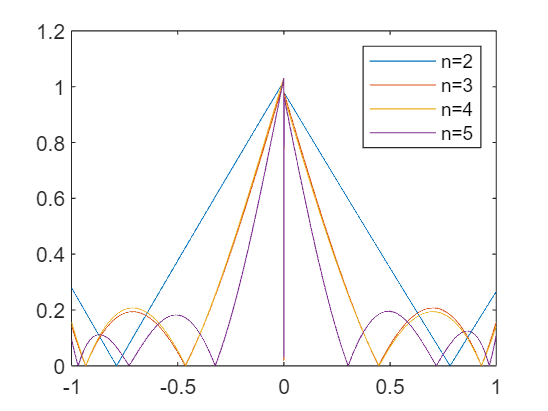

f = @(x)(x == 0).*0 + (x > 0).*(1) + (x < 0).*(-1);
N = [2,3,4,5];
x = -1:.001:1;
for i = 1:4
    cheb(i,:) = Chebyshev_approx(f,N(i),x);
    error(i,:) = abs(f(x) - cheb(i,:));
end
plot(x,error(1,:),x,error(2,:),x,error(3,:),x,error(4,:))
legend('n=2','n=3','n=4','n=5')

No, we can't make error as small as possible by increasing N as seen in the graph.

Functions

1.

function [p] = Chebyshev_approx(f,n,x)
p=0;
a = zeros(1,n+1);
for i = 0:n
    T_i = @(x)cos(i*x);
    F =@(x)f(cos(x)).*T_i(x);
    if i == 0 
        a(i+1)=(1/pi)*(composite_simpsons(F,0,pi,100));
        p=p+a(i+1)*T_i(acos(x));
    else
        a(i+1)=(2/pi)*(composite_simpsons(F,0,pi,100));
        p=p+a(i+1)*T_i(acos(x));
    end
end
end
function [output] = composite_simpsons(f,a,b,n)
h=(b-a)/n;
x=a:h:b;
F=f(x);
output = sum(h/3*(F(1:2:end-2)+4*F(2:2:end-1)+F(3:2:end)));
end
